%load the data table
if ~exist('celtab','var')
    load celtab.mat;
end
runsection = true;

Plot final yield over alpha for various amounts of cellulose

runsection = true;
if runsection
    figure
    hold on;
    xdat = celtab.alpha;
    %ydat = log10(celtab.biomass_final);
    ydat = (celtab.biomass_final);
    serieslabels = unique(celtab.cellulose_init);
    for i = 1:length(serieslabels)
        ci = serieslabels(i);
        idx = celtab.cellulose_init == ci;
        p = plot(xdat(idx),ydat(idx),'-o');
    end
    xlabel('Alpha');
    ylabel('Final Biomass (g)');
    title('Media-dependent change in yield');
    lgd = legend(arrayfun(@(x) string(x),serieslabels),'Location','best');
    title(lgd,'Initial Cellulose (mmol)');
    hold off;
end

if runsection    
    figure
    yield = celtab.biomass_final;
    Z = reshape(yield,[length(unique(celtab.alpha)) length(unique(celtab.cellulose_init))]);
    surf(unique(celtab.alpha), unique(celtab.cellulose_init), Z');
    xlabel('Alpha');
    ylabel('Cellulose');
    zlabel('Yield');
    
end

view([54.9000 50.0000])
runsection = false;

Regression to determine degree of relationship

lm1 = fitlm(celtab,'biomass_final ~ (cellulose_init + alpha)^2')

yield = celtab.biomass_final;
predictors = ones([length(yield) 1]); %When computing statistics, X should include a column of 1s so that the 
% model contains a constant term. The F statistic and its p value are computed under this assumption, 
% and they are not correct for models without a constant.
predictors = [predictors, celtab.cellulose_init];
predictors = [predictors, celtab.alpha];
predictors = [predictors, sin(celtab.alpha)];
predictors = [predictors, celtab.alpha .^ 3];
predictors = [predictors, celtab.alpha .^ 2];
predictors = [predictors, sin(celtab.alpha) .^ 2];
predictors = [predictors, celtab.alpha .^ 4];
predictors = [predictors, sin(celtab.alpha) .^ 3];
predictors = [predictors, sin(celtab.alpha) .^ 4];
predictors = [predictors, celtab.alpha .^ 5];
predictors = [predictors, sin(celtab.alpha) .^ 5];
predictors = [predictors, sin(celtab.alpha .^ 2)];
predictors = [predictors, sin(celtab.alpha .^ 3)];
predictors = [predictors, celtab.cellulose_init .* celtab.alpha];
predictors = [predictors, celtab.cellulose_init .^ 2];
predictors = [predictors, sin(celtab.cellulose_init .* celtab.alpha)];
predictors = [predictors, sin(celtab.cellulose_init .* (celtab.alpha .^ 2))];
[b,bint,r,rint,stats] = regress(yield,predictors)
%b contains the coefficient estimates
%bint is the 95% confidence intervals for the coefficient estimates
%r is the residuals
%stats contains, in order, the R2 statistic, the F statistic and its p value, and an estimate of the error variance.
%remember R-squared = Explained variation / Total variation
scatter(yield,r)
xlabel('Yield')
ylabel('Residual')

rdat = celtab(:,{'biomass_final' 'alpha' 'cellulose_init'});
rdat.sina = sin(rdat.alpha);
rdat.sina2 = sin(rdat.alpha) .^ 2;
rdat.sin2a = sin(rdat.alpha .^2);
rdat.sina3 = sin(rdat.alpha) .^ 3;
rdat.sin3a = sin(rdat.alpha .^3);
rdat.sina4 = sin(rdat.alpha) .^ 4;
rdat.sin4a = sin(rdat.alpha .^4);
rdat.sina5 = sin(rdat.alpha) .^ 5;
rdat.sin5a = sin(rdat.alpha .^5);
rdat.sina6 = sin(rdat.alpha) .^ 6;
rdat.sin6a = sin(rdat.alpha .^6);
rdat.sina7 = sin(rdat.alpha) .^ 7;
rdat.sin7a = sin(rdat.alpha .^7);
rdat.sina8 = sin(rdat.alpha) .^ 8;
rdat.sin8a = sin(rdat.alpha .^8);
rdat.sina9 = sin(rdat.alpha) .^ 9;
rdat.sin9a = sin(rdat.alpha .^9);
rdat.sina10 = sin(rdat.alpha) .^ 10;
rdat.sin10a = sin(rdat.alpha .^10);
lm2 = stepwiselm(rdat,'biomass_final ~ 1 + cellulose_init * (alpha + sina + sina2 + sin2a + sina3 + sin3a + sina4 + sin4a + sina5 + sin5a + sina6 + sin6a + sina7 + sin7a + sina8 + sin8a + sina9 + sin9a + sina10 + sin10a)')

scatter(yield,lm2.Residuals.Raw)
scatter(yield,lm2.Residuals.Pearson)
scatter(yield,lm2.Residuals.Studentized)
scatter(yield,lm2.Residuals.Standardized)
%lm3 = stepwiselm(rdat,'biomass_final ~ 1 + cellulose_init * (alpha + sina + sina3 + sin3a + sina4 + sin4a)')

%Recreate the projected curve
a = 0:0.1:2.5; %alphas
c = 0.1:0.1:3; %cellulose
x = zeros(length(a),length(c));
for i = 1:length(a)
    for j = 1:length(c)
        x(i,j) = 0.015484 - (0.00070458 * a(i)) + (0.041487 * c(j)) - (0.013755 * sin(a(i) .^3)) - (0.046528 * a(i) * c(j)) + (0.024124 * c(j) * sin(a(i) .^3));
    end
end
surf(a,c,x', max(x',0))
xlabel('Alpha')
ylabel('Cellulose')
zlabel('Yield')
view([54.9000 50.0000])
hold off;


**Test Predictions**

The fit predicts an improvement at alpha=2.2, cel=0.1 as compared to alpha = 2.1, 2.4

% Build models
v.initcellulose = 0.1;
v.defaultbound = 10; %default exchange upper bound
v.maxEnzymeRate = 1; %maximum enzyme:biomass ratio by weight for fixed production. 1:1 w/ alpha=1 should mean half of all amino acids go into enzyme
v.alpha = 0.1; %fixed percentage of the maximum enzyme rate being expressed
v.kcat_cel = 0.01; %mmol converted / mmol enzyme / second  %TODO: Confirm units
v.km_cel = 0.125; %Units = mmoles/cm^3
v.km_glc = 0.01; %millimoles/cm^3.
v.vmax_glc = 10;
v.glcpercellulose = 218.2;
v.biomassperglc = 1/(1.447e9); 
v.glcuptakerate = -10; %bound for the GLC import reaction
v.xdim = 1;
v.ydim = 1;
v.diff_cel = 0; %Diffusion constants
v.diff_enz = 1e-6; %Default is 1e-6;
v.diff_glc = 1e-6;
v.initglc = 1e-8; %needed to bootstrap production
v.initmedia = 1; %amount of all other media added
v.maxcycles = 200;
v.timestep = 3; %1/(60*60); %1/3600 hours = 1 second. CAUTION: Make sure this agrees with the units in kcat.
v.filepath = 'C:\sync\biomes\cellulose\optima\temp';
v.writemedialog = false;
v.writebiomasslog = true;
v.writefluxlog = false;
v.lograte = 1;
v.maxspacebiomass = 1000;
v.spaceWidth = 1; %1cm, so v=1mL and most media are 1 millimolar
v.lograte = 2;
model_default = load('C:\sync\biomes\models\iJO1366 (1).mat'); %model with metabolite names normalized
model_default = model_default.iJO1366;

v.alpha = 2.2;
%model1 = buildEcoliModel(v,model_default,'2.2');
%model1 = executeModel(model1);
v.alpha = 2.1;
%model2 = buildEcoliModel(v,model_default,'2.1');
%model2 = executeModel(model2);
v.alpha = 2.4;
%model3 = buildEcoliModel(v,model_default,'2.4');
%model3 = executeModel(model3);

%expected values are: a=2.1: 0.065, a=2.2: 0.185, a=2.4: -0.004/NG
[max(model2.biomass) max(model1.biomass) max(model3.biomass)]


**spot check a few coordinates**


%let's use alpha = .1:.5, cel = 1.5
a = 0.1:0.05:0.5;
arows = ismember(celtab.alpha,a);
crows = (celtab.cellulose_init == 1.5) %| (celtab.cellulose_init == 2);

crows = 344×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
  

rows = arows & crows;
t = celtab(rows,:);

%plot glc over time
plotGlcRates(t.model)

ans =   Figure (43) with properties:

      Number: 43
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


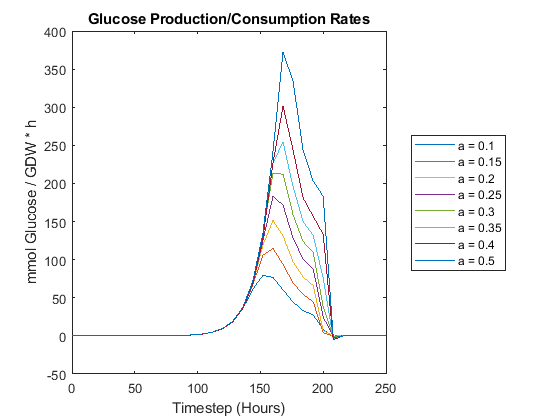

xlim([0 250])

plotGlucoseTimecourse(t.model)

ans =   Figure (44) with properties:

      Number: 44
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


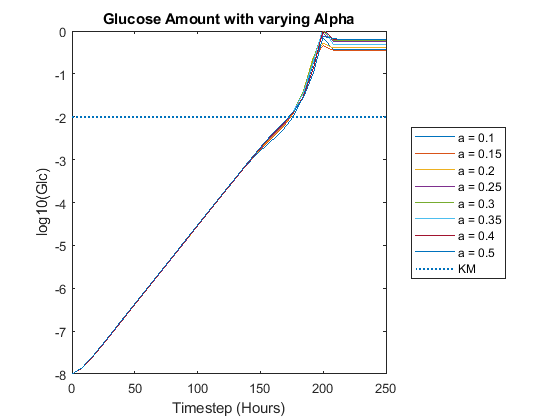

xlim([0 250])


%plot cellulose over time
plotCelluloseTimecourse(t.model)

ans =   Figure (45) with properties:

      Number: 45
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


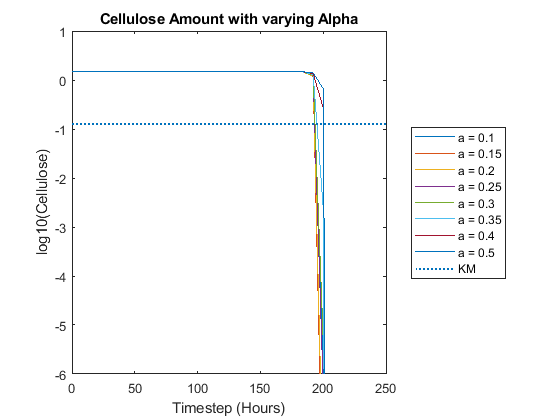

xlim([0 250])

plotCelluloseTimecourse(t.model)

ans =   Figure (46) with properties:

      Number: 46
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


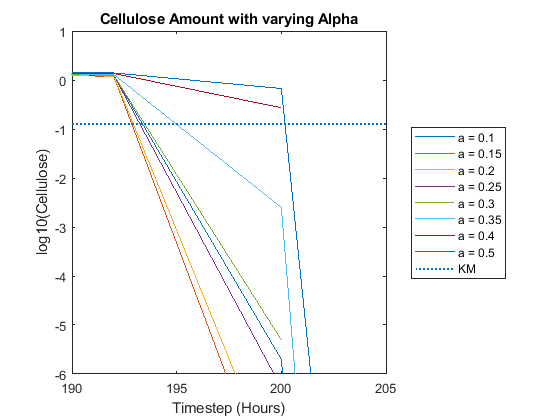

xlim([190 205])


%plot enzyme over time
plotEnzymeTimecourse(t.model)

ans =   Figure (47) with properties:

      Number: 47
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


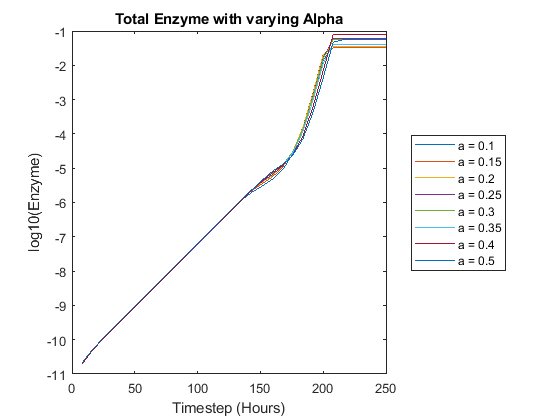

xlim([0 250])

plotEnzRates(t.model)

ans =   Figure (48) with properties:

      Number: 48
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


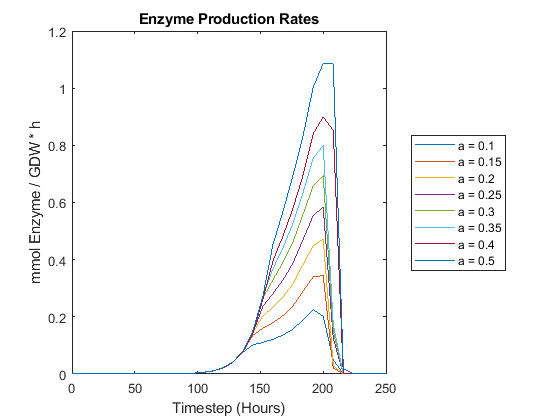

xlim([0 250])


%plot biomass over time
plotBiomassOverTime(t.model)

ans =   Figure (49) with properties:

      Number: 49
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


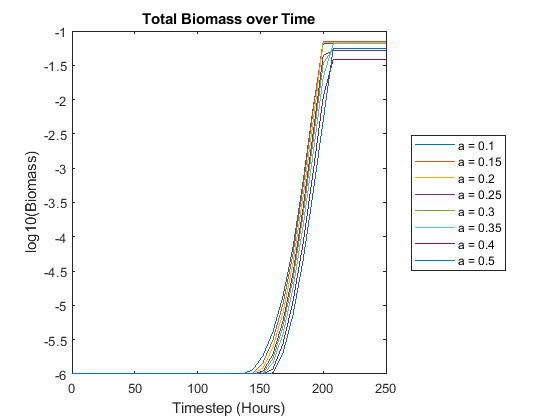

xlim([0 250])